# Project Objective

% This project was done for my Digital Signal Processing Course during my
% Spring 2025 Semester as a graduate student. My professor tasked the
% graduate students to gain an understanding of how the Kalman filter
% works through a chosen project. For my project, I chose to make a radar tracker 
% that tracked the position of a target traveling at a constant velocity and starting
% from rest. The model used for this project is a linear motion model that was
% scrambled using the 'randn' function to generate random points that the
% Kalman filter then can smooth out to get accurate estimates.

% Measures: Position Only

% clear command window, figures and workspace
clear all
close all
clc

## Data Section

dt = 0.1;          % sampling interval, smaller dt = better filter tracking
t = 0:dt:20;       % timing vector
xi = 0;            % initial position
v = 20;            % 20 m/s constant velocity
sigma = 20;        % standard deviation of measurement noise

## Motion Model

% Linear Motion Model
x = xi + v*t; % constant velocity assumed, acceleration becomes part of process noise

% simulate radar measurements
z = x + sigma*randn(size(t)); % radar measurement vector

## State Space Model Definition

% 2 States
% 1 Outputs
% 0 Inputs

% State Transition Matrix (n x n)
A = [1 dt; 0 1]; % derived from Kinematics, position is updated by velocity                  

% Control Input Matrix (n x m)
% although we do not have any control input, we still want to inject 
% process noise into the position and velocity so that Q may be calculated!
B = eye(2); % indpendently inject process noise into each state

% State-to-Measurement Matrix (called 'H' for Kalman filtering) (p x n)                      
C = [1 0]; % measuring position only

% Feedthrough Matrix (p x m)
% input has no instantaneous affect on the measurement, so normally D = 0
% we use zeros(1, 2) so size(D) = size(C)
D = zeros(1, 2);

## Noise Covariance

% Process Noise Covariance (uncertainty in model dynamics)
% - smaller Q: motion model is accurate
% - larger Q: motion model is uncertain (increase predicted uncertainty)
Q = [1 0; 0 1];

% Measurement Noise Covariance (uncertainty in sensor measurements)
% - smaller R: filter trusts measurements more (believes sensor is accurate)
% - larger R: filter trusts model more (believes that the sensor is noisy)
R = sigma^2;

## MATLAB 'kalman()' Filter Function Design

% Form the state-space system
sys = ss(A, B, C, D, dt);

% Creating Kalman Filter from the Built-In 'kalman' Command
[kalmf, L, P] = kalman(sys, Q, R); % MATLAB generated kalman filter,
% kalmf = Kalman filter system
% L = Kalman Gain
% P = Steady-state error covariance

% Simulate kalmf on radar measurements
[y, time, x_kalmf_estimates] = lsim(kalmf, z, t);
% y = sensor reconstruction reading (reconstructed estimate based on internal state estimates)
% time = same timing vector as 't'
% x_kalmf_estimates = internal state estimates at each time step

## Recursive Kalman Filter Implementation

% Initialize state and covariance
X_est = [0; 20]; % Initial position and velocity
P_est = [10^2 0; 0 1^2]; % Initial covariance estimate

% Preallocate for storage
X_estimates = zeros(length(t), 2);
% Portion followed example on MathWorks website
% kalman filter loop
for k = 1:length(t)
   
    % Measurement Update (Correction step)
    Mxn = P_est * C' / (C * P_est * C' + R);    % Kalman Gain
    X_est = X_est + Mxn * (z(k) - C * X_est);   % state estimate
    P_est = (eye(2) - Mxn * C) * P_est;         % covariance estimate

    % Store corrected estimate
    X_estimates(k, :) = X_est;

    % Time Update (Prediction step)
    X_est = A * X_est;             % Predict next state
    P_est = A * P_est * A' + Q;    % Predict next covariance
end
  

## Plots

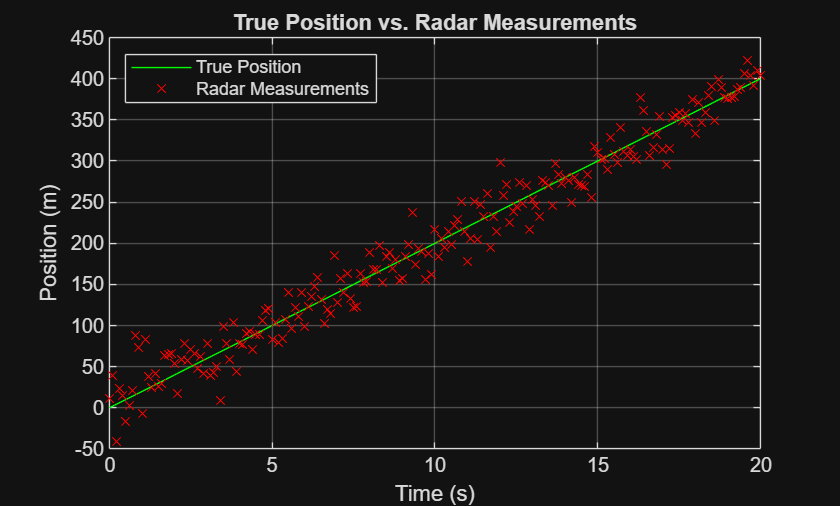

% True Position vs. Noisy Measurements
figure

% True Position
plot(t, x, 'g-')
hold on

% Noisy Measurements
plot(t, z, 'rx')

legend('True Position', 'Radar Measurements', 'location', 'northwest');
xlabel('Time (s)');
ylabel('Position (m)');
title('True Position vs. Radar Measurements');
grid on;

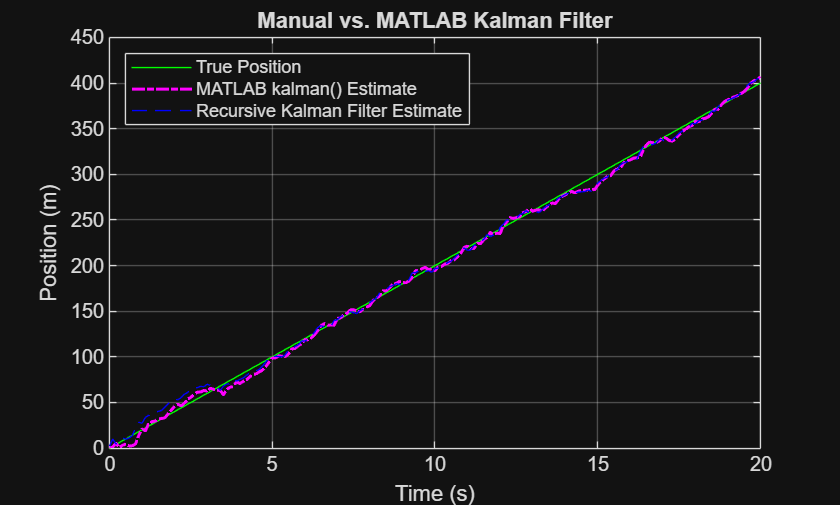

% Kalman Filter Plots Against True Position
figure

% True Position
plot(t, x, 'g-')
hold on

% MATLAB 'Kalman' Estimate
plot (t, x_kalmf_estimates(:,1), 'm-.', 'LineWidth', 1.5);
hold on

% Recursive Kalman Filter Estimates
plot(t, X_estimates(:, 1), 'b--')

legend('True Position', 'MATLAB kalman() Estimate', 'Recursive Kalman Filter Estimate', 'location', 'northwest');
xlabel('Time (s)');
ylabel('Position (m)');
title('Manual vs. MATLAB Kalman Filter');
grid on;

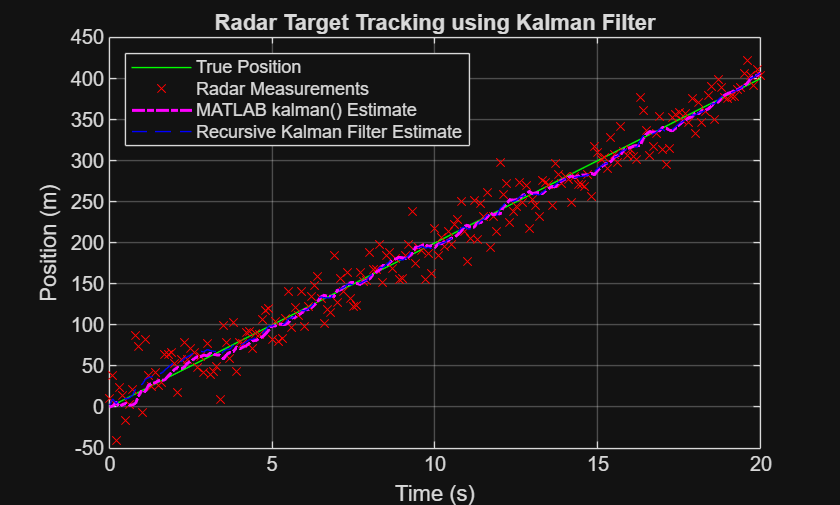

% Kalman Filters vs. True Position vs. Noisy Measurements
figure

% True Position
plot(t, x, 'g-')
hold on

% Noisy Measurements
plot(t, z, 'rx')
hold on

% MATLAB 'Kalman' Estimates
plot(t, x_kalmf_estimates(:,1), 'm-.', 'LineWidth', 1.5);
hold on

% Recursive Kalman Filter Estimates
plot(t, X_estimates(:, 1), 'b--')

legend('True Position', 'Radar Measurements', 'MATLAB kalman() Estimate', 'Recursive Kalman Filter Estimate', 'location', 'northwest');
xlabel('Time (s)');
ylabel('Position (m)');
title('Radar Target Tracking using Kalman Filter');
grid on;

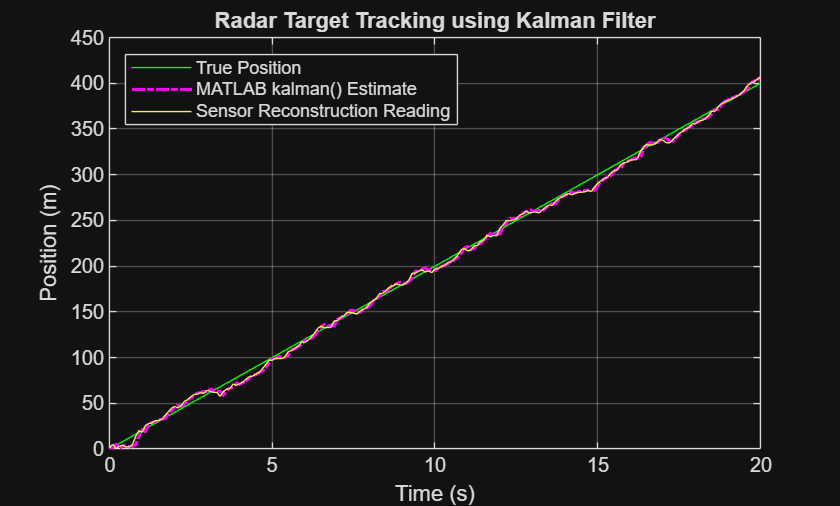

% True Position vs. Position State Estimates vs. Sensor Reconstruction Reading

% NOTE: The sensor reconstruction reading is the predicted measurement computed from the estimated states.

figure

% True Position
plot(t, x, 'g-')
hold on

% MATLAB 'Kalman' Estimates
plot(t, x_kalmf_estimates(:,1), 'm-.', 'LineWidth', 1.5);
hold on

% Sensor Reconstruction Reading ('y' from MATLAB 'kalman()' filter)
plot(t, y(:, 1))

legend('True Position', 'MATLAB kalman() Estimate', 'Sensor Reconstruction Reading', 'location', 'northwest');
xlabel('Time (s)');
ylabel('Position (m)');
title('Radar Target Tracking using Kalman Filter');
grid on;

## Accuracy Checks

% Extract position estimates
man_est   = X_estimates(:, 1);         % Manual KF position (Nx1)
kalmf_est = x_kalmf_estimates(:, 1);   % MATLAB kalmf position (Nx1)
truth     = x(:);                      % True position (Nx1)

% MAPE: Mean Absolute Percentage Error
% ACC: Accuracy

% Mask out zero values in truth to avoid divide-by-zero in MAPE
mask = truth ~= 0;

% Manual KF metrics
MAPE_manual = mean(abs((man_est(mask) - truth(mask)) ./ truth(mask))) * 100;
ACC_manual  = 100 - MAPE_manual;

% MATLAB kalmf metrics
MAPE_kalmf = mean(abs((kalmf_est(mask) - truth(mask)) ./ truth(mask))) * 100;
ACC_kalmf  = 100 - MAPE_kalmf;

% Print results
fprintf('Manual Kalman Filter: \nMAPE: %.2f%% \nAccuracy: %.2f%%\n', MAPE_manual, ACC_manual);

Manual Kalman Filter: 
MAPE: 7.87% 
Accuracy: 92.13%


fprintf('\nMATLAB kalmf Command: \nMAPE: %.2f%% \nAccuracy: %.2f%%\n', MAPE_kalmf, ACC_kalmf);


MATLAB kalmf Command: 
MAPE: 5.73% 
Accuracy: 94.27%
